# 1.a visualizing a function


x1 = 0;
x2 = 2;
n = 500;

t = linspace(x1,x2,n)

t =          0    0.0040    0.0080    0.0120    0.0160    0.0200    0.0240    0.0281    0.0321    0.0361    0.0401    0.0441    0.0481    0.0521    0.0561    0.0601    0.0641    0.0681    0.0721    0.0762    0.0802    0.0842    0.0882    0.0922    0.0962    0.1002    0.1042    0.1082    0.1122    0.1162    0.1202    0.1242    0.1283    0.1323    0.1363    0.1403    0.1443    0.1483    0.1523    0.1563    0.1603    0.1643    0.1683    0.1723    0.1764    0.1804    0.1844    0.1884    0.1924    0.1964



f_s = n/(x2-x1) % f_s = n/duration = n/(x2-x1)

f_s = 250

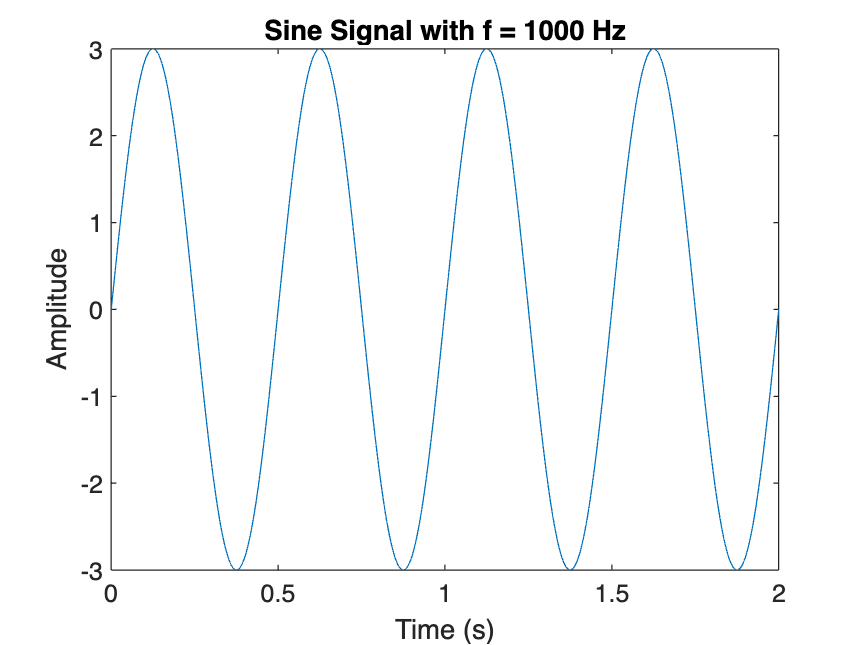


t1 = [x1:1/f_s:(x2-1)]; 

x = 3*sin(2*pi*1000*t1);


plot(t1, x);
xlabel('Time (s)');
ylabel('Amplitude');
title('Sine Signal with f = 1000 Hz');

# 1.b compute sine function

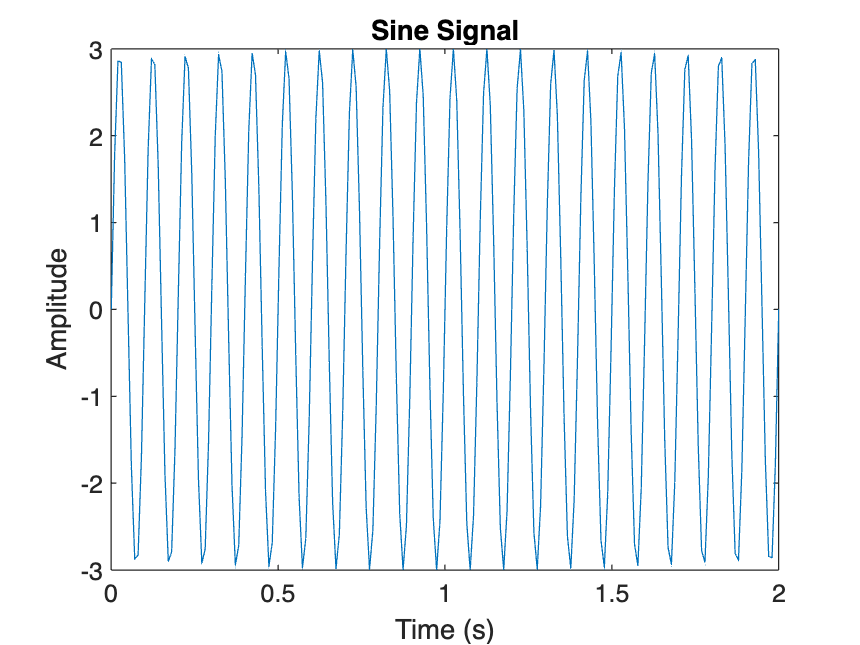

x =          0    1.7710    2.8590    2.8443    1.7326   -0.0474   -1.8090   -2.8730   -2.8288   -1.6937    0.0947    1.8466    2.8862    2.8127    1.6544   -0.1420   -1.8837   -2.8988   -2.7959   -1.6147    0.1893    1.9203    2.9106    2.7784    1.5746   -0.2366   -1.9564   -2.9217   -2.7602   -1.5340    0.2837    1.9921    2.9321    2.7413    1.4932   -0.3309   -2.0273   -2.9418   -2.7217   -1.4519    0.3779    2.0619    2.9507    2.7014    1.4103   -0.4248   -2.0961   -2.9589   -2.6805   -1.3683


% computeSine(A, f, f_s, x1, x2)

x = compute_sine(3, 10, 100, 0, 2)

# 2. Generating a random signal with Gaussian distribution

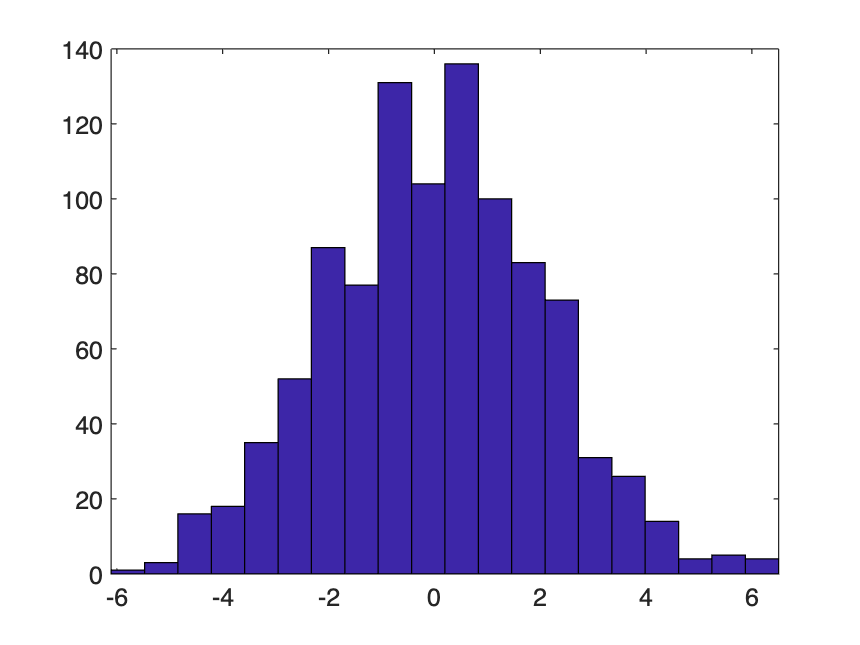

x=2*randn(1000,1);
histogram(x,20);

# 4. Adding white Gaussian noise to a signal 

**Use the function addNoise.m to generate four sines (frequency of 100Hz, Amplitude equal to 1, sampling frequency 1kHz, duration 1s) with white Gaussian noise SNRs = [5, 15, 20, 50].**

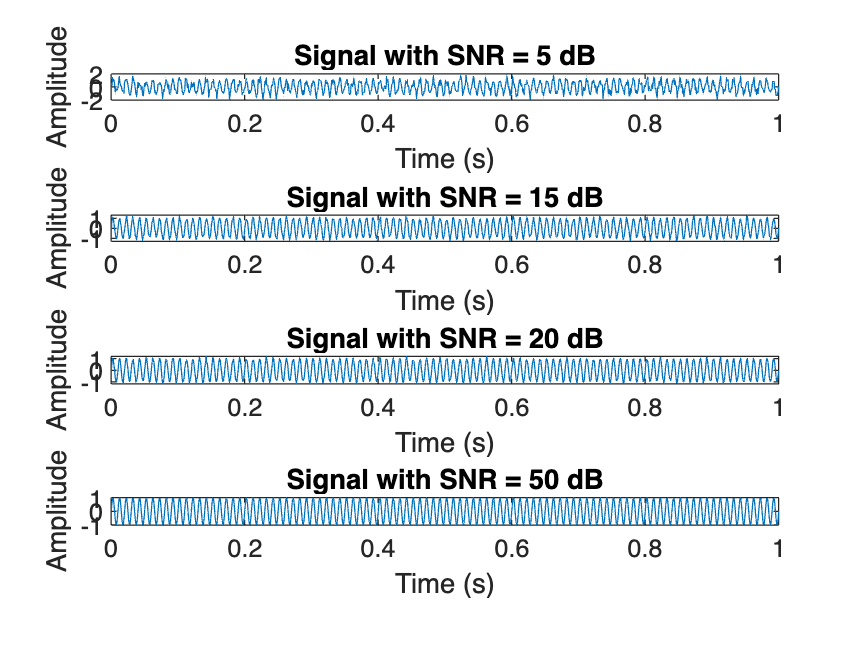

f = 100;
A = 1;
f_s = 1000;
d = 1;

% f_s = n/duration
n = f_s*d;
t = linspace(0,d,n);
x = A*sin(2*pi*f*d);

% Generate four sine waves with different SNRs
SNRs = [5, 15, 20, 50];
signals = cell(1, length(SNRs)); % Initialize cell array to store signals


for i=1:length(SNRs)
    snr=SNRs(i);
    x = A * sin(2*pi*f*t); % Generate sine wave
    signals{i} = addNoise(x, t, snr); % Add noise and store the signal
end

% Plot the signals
figure;
for i = 1:length(SNRs)
    subplot(length(SNRs), 1, i);
    plot(t, signals{i});
    title(['Signal with SNR = ', num2str(SNRs(i)), ' dB']);
    xlabel('Time (s)');
    ylabel('Amplitude');
end

# 5. Fourier Transform

Calculate the Fourier Transform of x1(t) (sine with A=1, f=10Hz, fc=1kHz), by using fft.m. 

Plot the fft of the signal x1. What remarks? Plot the module (use the function abs.m). 

When analyzing the frequency components of signals, it can be helpful to shift the zero- frequency components to the center. You can use the precompiled function fftshift.m. 

Represent the amplitude spectrum respect an ordered frequency axis [-fs/2: fs/2]. 

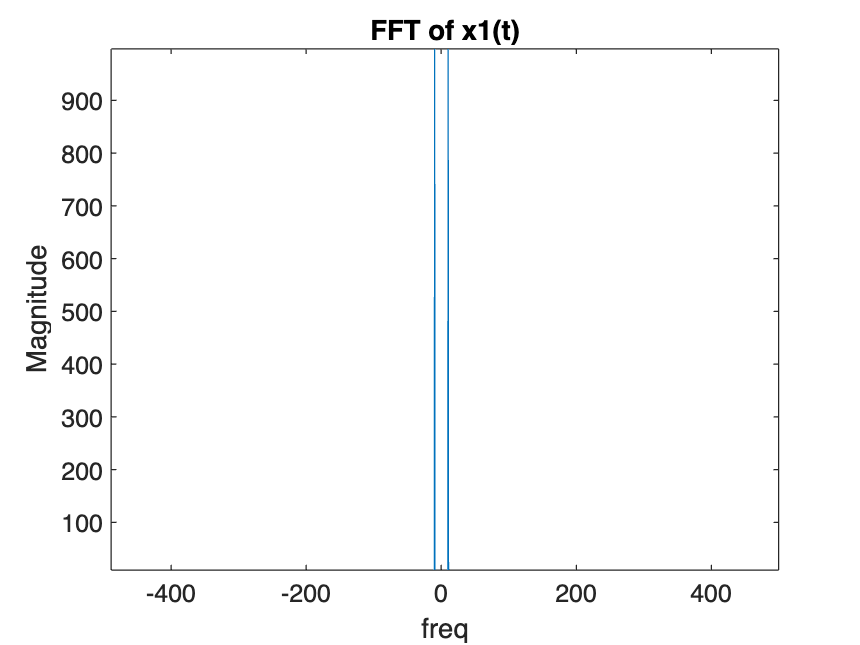

A = 1;
f = 10;
fc = 1000;
duration = 2;

% Calculate the number of samples (n) based on the sampling frequency (fc) and duration
%fc = n/duration
n = duration*fc;

% Generate the time vector (t) from 0 to duration with n samples
t=linspace(0,duration,n);
% t = [0:duration/(n-1):2];

% Generate the sinusoidal signal x1(t)
x1 = A*sin(2*pi*f*t);

% Compute the Fourier Transform of x1(t) using fft
Fourier = fft(x1);

% Calculate the magnitude spectrum (absolute values of Fourier coefficients)
Fourier_abs = abs(Fourier);

% Shift the zero-frequency component to the center using fftshift
shift = fftshift(Fourier_abs);

% Generate the frequency axis ranging from -fc/2 to fc/2 with n points
frequencies = linspace(-fc/2, fc/2, n);

% Plot the shifted FFT against the time vector (t)
figure;
plot(frequencies, shift);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('FFT of x1(t)');

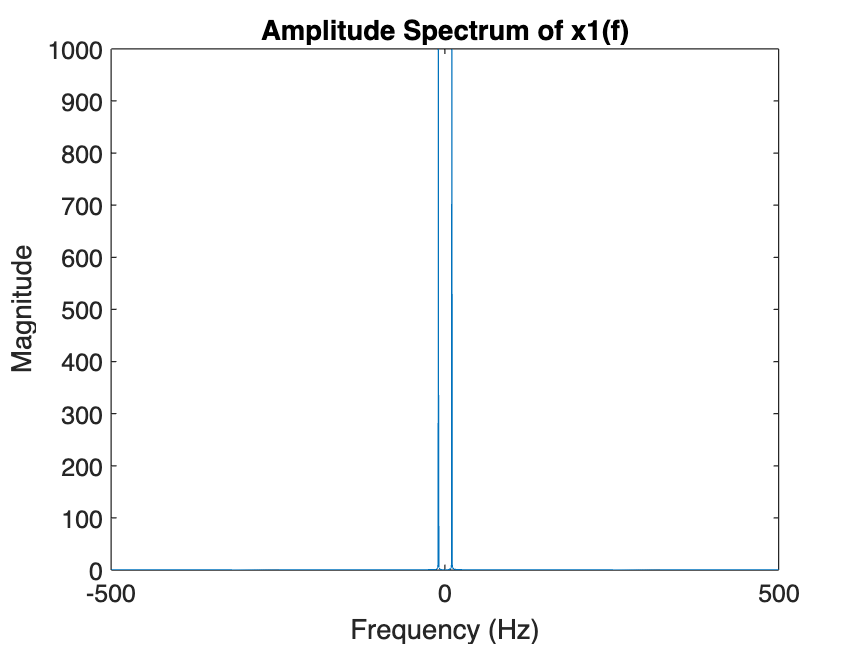


% Plot the amplitude spectrum (frequency domain) against the frequency axis
figure;
plot(frequencies, shift);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Amplitude Spectrum of x1(f)');

Perform the same analysis on a sinusoidal signal x2(k) with a frequency of 120Hz, and a sinusoidal signal x3(k) composed of two sinusoids (100Hz and 120Hz, obtained as x1(k)+x2(k)) 

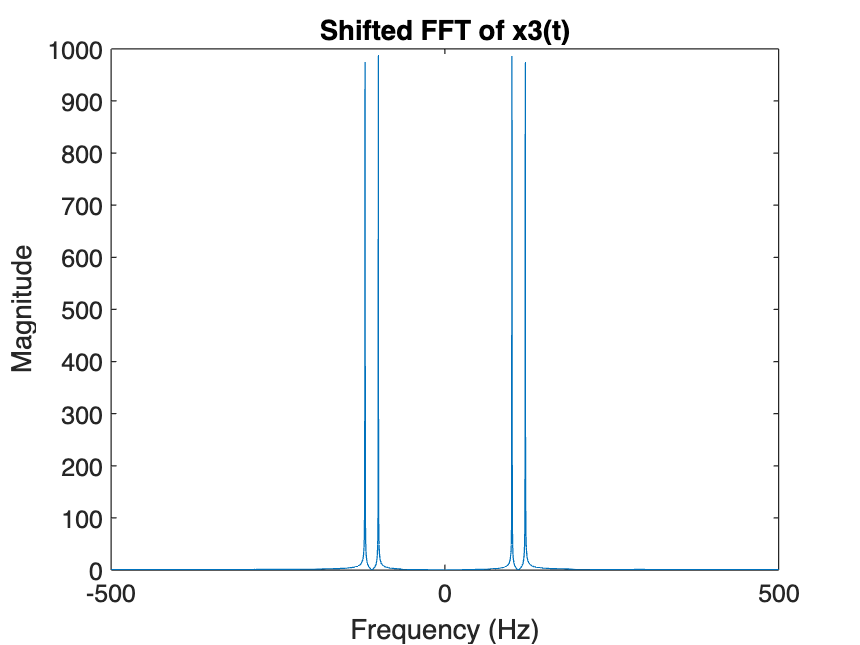

f1 = 100;
f2 = 120;

fc = 1000;
duration = 2;

%fc = n/duration
n = duration*fc;

t=linspace(0,duration,n);
% t = [0:duration/(n-1):2];

x1 = sin(2*pi*f1*t);
x2 = sin(2*pi*f2*t);

x3 = x1 + x2;

Fourier = fft(x3);
Fourier_abs = abs(Fourier);
shift = fftshift(Fourier_abs);

frequencies = linspace(-fc/2, fc/2, n);

% Plot the shifted FFT
figure;
plot(frequencies, shift);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Shifted FFT of x3(t)');

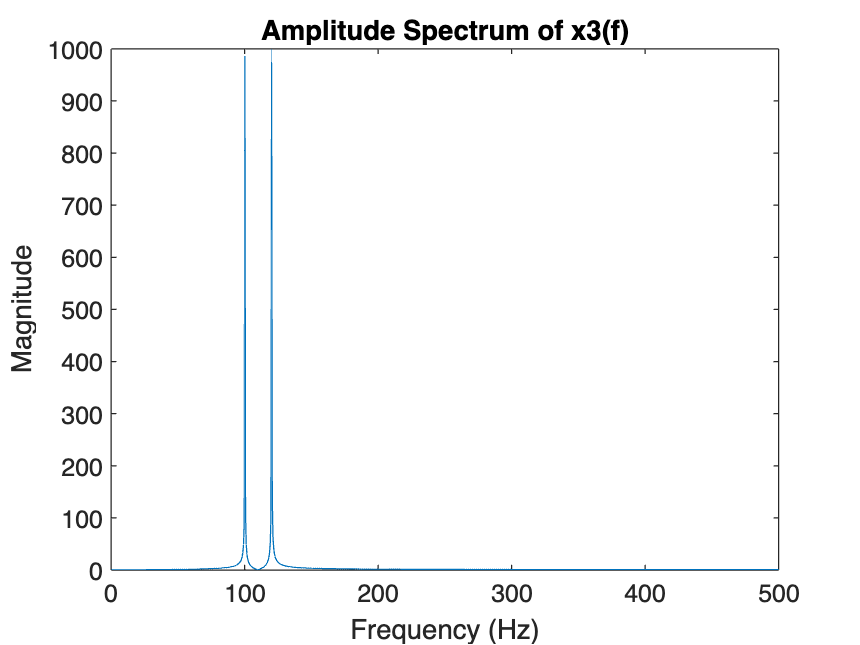


%{
% Plot the amplitude spectrum
figure;
plot(frequencies, shift);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Amplitude Spectrum of x3(f)');
%}

% Plot the amplitude spectrum
positive_frequencies = linspace(0, fc/2, n/2); % Only positive frequencies
Fourier_abs_pos = Fourier_abs(1:n/2); % Extract positive frequency components
figure;
plot(positive_frequencies, Fourier_abs_pos); % Plot only positive frequencies
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Amplitude Spectrum of x3(f)');